**Notebook to Create Climatologies**

This exercise will show you how to download model results from the  ERDDAP server, create a climatology, and compare current results to the  climatology.

**Learning Goals**

After completing these exercises you will be able to:

- describe what a climatology is and explain how you generate one

- describe anomalies from a climatology and explain how to create them

- for one tracer field, describe how 2024 compares to previous Mays, considering anomalies and also how large those anomalies are

**Set-up**

% choose region of interest in model grid points
ygmin=700; ygmax=800;  % note, we are typing these in below
xgmin=110; xgmax=210;
% region for profile
xcmin=120; xcmax=160;
sy=725;

Uname='https://salishsea.eos.ubc.ca/erddap/griddap/';
Ufields={'ubcSSn3DMeshMaskV21-08.nc?tmask';
    'ubcSSnBathymetryV21-08.nc?bathymetry';
    'ubcSSnBathymetryV21-08.nc?latitude';
    'ubcSSnBathymetryV21-08.nc?longitude';
    'ubcSSg3DPhysicsFields1hV21-11.nc?salinity';
    'ubcSSn3DMeshMaskV21-08.nc?gdept_0'};
Ugrd={'[(0.0):1:(39.0)][(700.0):1:(800.0)][(110.0):1:(210.0)]';
    '[(700.0):1:(800.0)][(110.0):1:(210.0)]';
    '[(700.0):1:(800.0)][(110.0):1:(210.0)]';
    '[(700.0):1:(800.0)][(110.0):1:(210.0)]';
    '[(0.5):1:(250.0)][(725.0):1:(725.0)][(120.0):1:(160.0)]';
    '[(0.5):1:(39.0)][(725.0):1:(725.0)][(120.0):1:(160.0)]'};
Sname={'tmask.nc';'bathymetry.nc';
    'latitude.nc'; 'longitude.nc'; 'salinity.nc'; 'depth.nc'};
options=weboptions;  % Need this because SalishSeacast ERDDAP server is slow
options.Timeout=Inf;

**Grid (where the land is)**

% date for undated files is first day of the time series
days=fix(datenum(2007,1,1));
dstr=datestr(days,'yyyy-mm-dd');
fprintf('Getting data for %s...\n\n',dstr)

Getting data for 2007-01-01...




Udates0=sprintf('[(%sT00:00:00Z):1:(%sT00:30:00Z)]',dstr,dstr)

Udates0 = '[(2007-01-01T00:00:00Z):1:(2007-01-01T00:30:00Z)]'

urlname=[Uname Ufields{1} Udates0 Ugrd{1}];
savename=Sname{1};
tic
outname=websave(savename,urlname,options);

Get the depth scales

urlname = [Uname Ufields{6} Udates0 Ugrd{6}]

urlname = 'https://salishsea.eos.ubc.ca/erddap/griddap/ubcSSn3DMeshMaskV21-08.nc?gdept_0[(2007-01-01T00:00:00Z):1:(2007-01-01T00:30:00Z)][(0.5):1:(39.0)][(725.0):1:(725.0)][(120.0):1:(160.0)]'

savename=Sname{6}

savename = 'depth.nc'

tic
outname=websave(savename,urlname,options);

and **Bathymetry, Latitude and Longitude**

urlname=[Uname Ufields{2} Ugrd{2}];
savename=Sname{2}
tic
outname=websave(savename,urlname,options);

savename = 'bathymetry.nc'

Error using websave (line 98)
Could not access server. https://salishsea.eos.ubc.ca/erddap/griddap/ubcSSnBathymetryV21-08.nc?bathymetry%5B%28700.0%29:1:%28800.0%29%5D%5B%28110.0%29:1:%28210.0%29%5D.

urlname=[Uname Ufields{3} Ugrd{3}];
savename=Sname{3}

savename = 'latitude.nc'

tic
outname=websave(savename,urlname,options);

urlname=[Uname Ufields{4} Ugrd{4}];
savename=Sname{4}

savename = 'longitude.nc'

tic
outname=websave(savename,urlname,options);

tmask = ncread(Sname{1},'tmask');
bathymetry = ncread("bathymetry.nc", 'bathymetry');

Plot the bathymetry

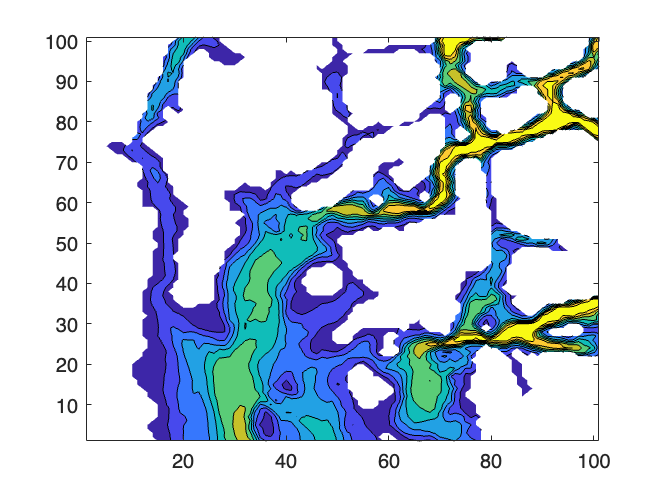

contourf(transpose(bathymetry))

With latitude and longitude

latitude = ncread("latitude.nc",'latitude');
longitude = ncread("longitude.nc", 'longitude');

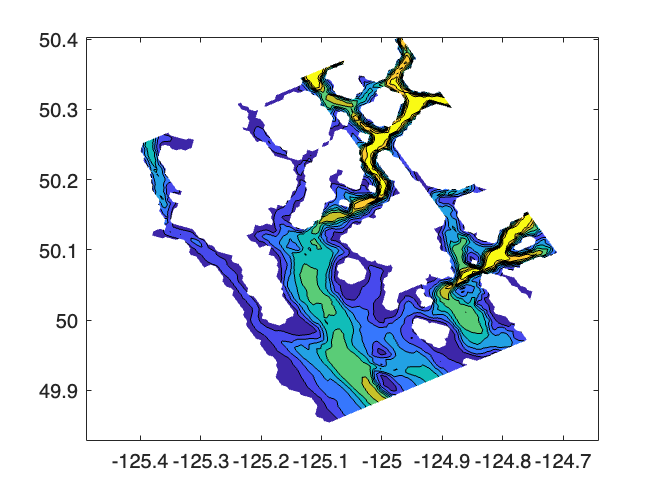

contourf(transpose(longitude), transpose(latitude), transpose(bathymetry))

## Exercise

Choose one of: (in consultation with the class so we get a bunch done!)

- surface salinity

- surface temperature

- surface nitrate

- depth integrated diatoms

- depth integrated flagellates

- vertical cross-section of salinity***

- vertical cross-section of temperature

- vertical cross-section of oxygen

- vertical cross-section of dissipation

- vertical cross-section of vertical eddy diffusivity

Build a daily climatology for your field for May 15.  Calculate the  anomalies for 2024.  Calculate the standard deviation over the time  series.  Determine is the anomalies are significant.

Below I give an example, for a vertical cross-section of salinity (for May 11 as May 15 hasn't happened yet!).

for year=2007:2024
    ii = year - 2006;
    mystring = sprintf('%s-05-11T20:30:00', string(year));
    Udates = strcat('[(',mystring,')]');

    urlname=[Uname Ufields{5} Udates Ugrd{5}];
    savename=strcat('Y', string(year), Sname{5})
    tic
    outname=websave(savename,urlname,options);
end

savename = "Y2007salinity.nc"

savename = "Y2008salinity.nc"

savename = "Y2009salinity.nc"

savename = "Y2010salinity.nc"

savename = "Y2011salinity.nc"

savename = "Y2012salinity.nc"

savename = "Y2013salinity.nc"

savename = "Y2014salinity.nc"

savename = "Y2015salinity.nc"

savename = "Y2016salinity.nc"

savename = "Y2017salinity.nc"

savename = "Y2018salinity.nc"

savename = "Y2019salinity.nc"

savename = "Y2020salinity.nc"

savename = "Y2021salinity.nc"

savename = "Y2022salinity.nc"

savename = "Y2023salinity.nc"

savename = "Y2024salinity.nc"

for year=2007:2023
    ii = year - 2006;
    savename=strcat('Y', string(year), Sname{5});
    salinity(ii,:,:) = ncread(savename,'salinity');
end
depth = ncread("depth.nc", 'gdept_0');

sal_climatology = squeeze(mean(salinity(1:16,:,:)));
contourf(1:41, squeeze(depth(1,1,1:31)), transpose(sal_climatology(:,:)),)

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

Error using contourf (line 57)
The size of Y must match the size of Z or the number of rows of Z.

colorbar;

## Question 1.

a) What do you see your field, what type of patterns?

*For  example, in my salinity cross-section, I see that near the surface there is fresher water on the east side of the cross-section.  This pattern  makes sense because there is more freshwater coming off the mainland  than the east side of Vancouver Island.  In addition, looking in  particular at the climatology, there is change in salinity at mid-depths at about grid point 132 with the water to the west saltier than the  water to the east.*

b) Why is the 2024 plot "noiser" than the climatology?  

You could plot the 2024 field side by side with the climatology to better see the differences.  However, an even better way to show the differences is to subtract them.  The **anomalies** are the 2024 field minus the climatology.

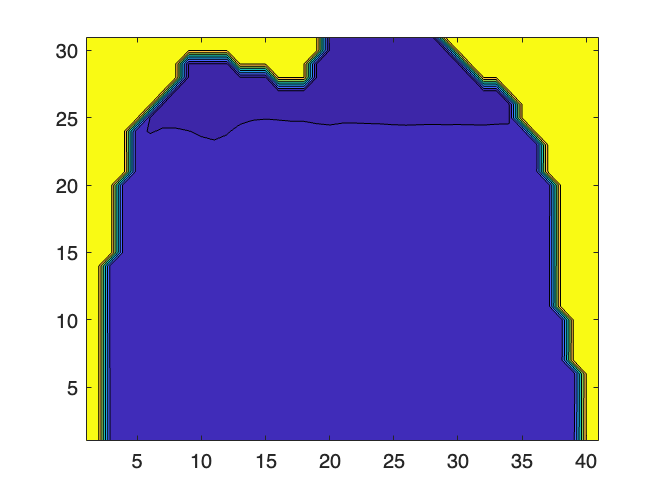

contourf(transpose(salinity(17) - sal_climatology),)

## Question 2.

a) How does 2024 compare to the climatology for your field?

*For  example, my salinity anomalies show that 2024 was saltier at the surface and at all depths on the western side.  Deep on the eastern side  though, it is fresher than usual.  That means, on the east side, the  stratification is weaker than usual.

b) What do you think it is different (what processes might be stronger/weaker)?  

To ask how anomalous this year is, for each spatial point we calculate a standard deviation over the time series.

% calculate and plot the standard deviation of salinity along the time,
% first, axis

## Question 3.

a) Can you explain the regions of high standard deviation?  What processes make them higher?

To look at how anomalous 2024 was, we can ask how many standard deviations is it from the mean?  Two is high, three is very high.

% subtract the climatology from 2024, divide by the standard deviation and
% plot

## Question 4.

a) For your field, how high are the anomalies?

Lastly we will ask if any other years look like 2024.  Here I am going to plot the normalized anomalies (divided by the standard deviation, but you  can choose what to look at: the raw field, the anomalies or the  normalized anomalies.

% plot a multi-panel figure with all the years

## Question 5.

a) For your field, does 2024 look like any of the other years?